# Signal-space simulation with propagation channel effects

This code performs a signal-space simulation of a digital communication scheme. It implements the following flowchart:

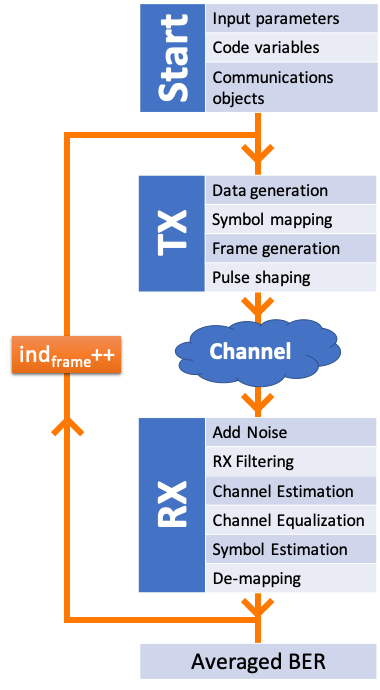

In most mobile communications, the data symbols to be transmitted are grouped within frames of certain durations (e.g., 10ms...) before transmission. This live script simlulates the transmission of such frames over a propagation channel model. At the receiver, the channel is estimated using pilot symbols in order to demodulate the received data symbols. The BER is then calculated by averaging over all transmitted frames

**Channel estimation**

Classically, reference signals are used in wireless communications to enable the channel estimation. The reference signals are dedicated pilot symbols known to both the transmitter and receiver. By comparing received pilot symbols with expected pilot symbols, a receiver can estimate the channel (which is the transfer function of the propagation between the transmitter and receiver):

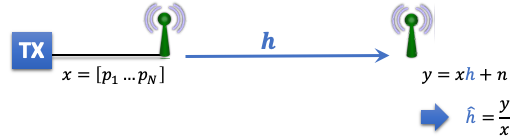

Here, the transmitted reference signal $x$ is composed of $N$ pilot symbols $[p_1\cdots p_N]$. Using $N$ pilot symbols enables to average the estimates $\hat{h}$ over $N$ and thus improve the estimate by averaging out the noise $n$. The data to be sent after the pilots will be equalized at the receiver using this channel averaged estimate.

The management of reference signals can be complicated, especially in 5G. They are typically optimized to avoid too large overhead (the more pilots the lower the effective data rate) and are now in 5G well suited for massive MIMO processing (where the number of channels can be large due to the large number of antennas of the base stations). In this live script, we will consider a simple example where the pilots are sent along with the data and are located at the begining of each frame to be transmitted as shown below.

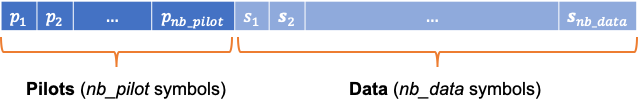

In this livescript, the transmitter sends *nb_frame* frames of *nb_data* data symbols along with *nb_pilot* pilot symbols. The channel is considered constant over a single frame. So the channel realization is updated at each frame. Furthermore, the channel is considered constant over frequency (narrowband assumption) and can be therefore represented by one scalar complex value per frame.

clc;                                        % Clear the command window screen
clear all;                                  % Erase all existing variables
close all;                                  % Close all figure windows

## Guidelines: what to do?

This code uses the following functions:

- generate_channel

- mapping_QAM

- raised_cosine

- convolution_TX

- convolution_RX

- symbol_estimation_QAM

- demapping_QAM

All the functions used in this live script have been developed in the previous 4 live scripts. So no additional code is required to run this 5th live script. The goal here is to understand how this 5th live script works and to investigate how the channel and all the parameters influence the performance of the communication.

In particular:

- Observe the constellation of received symbols with and without channel equalization (EQ)

- Compare how the BER is different between AWGN channel (i.e. no channel model, only noise at RX) and with Rayleigh or Rice channel

- Compare numerical BER in these three cases (AWGN/Rayleigh/Rice) with analytical results (see the last 3 lines of the codes)

- How the obtained performance depends on the number of pilot symbols used?

- How the Rice factor influences the BER?

- Modify this code to plot the BER as a function of SNR for the three different channels (AWGN/Rayleigh/Rice)

**Tips:** 

The number of frames should be large enough to obtain meaningful BER results. Keep in mind that the Rice/Rayleigh channels exhibit a statistical behaviour and so the number of channel realizations (equal to the number of frames) should be large enough to observe this statistical behaviour (otherwise the averaged BER value will not be representative of the scenario under consideration).

However, to observe the power spectrum and the constellations (TX/RX/RX-EQ), no need to simulate a large number of frames, one is enough! (this will save simulation time)

When simulating a large number of frames, do comment the figures (this will save simulation time).

## Input parameters

nb_frame = 10 ;                              % Number of frames to be transmitted
nb_data = 1000 ;                            % Number of data symbols per frame
nb_pilot = 10 ;                             % Number of pilot symbols per frame
nb_bit_per_symb = 4 ;                       % Number of bits per symbol
snr_dB = (1:15) ;                               % Signal-to-Noise Ratio at RX
rolloff = .5 ;                              % Roll-off factor
symb_rate = 100e6 ;                         % Symbol rate
sps = 2 ;                                   % Samples per symbol (oversampling ratio)
span = 16 ;                                 % Span of the pulse shaping filter

## Code variables

nb_bit = nb_data * nb_bit_per_symb  ;       % Number of data bits to be transmitted per frame                       
t_symb = 1 / symb_rate ;                    % Symbol duration
fs = symb_rate * sps ;                      % Sampling frequency 
ber_numerical = zeros( 1 , nb_frame ) ;     % Variable to store the calculated BER for each frame
bit_TX_data = randi( [0 1] , nb_bit , 1 ) ;                                 % Random bit generation 

**Comment**: The minimum sampling frequency *fs *depends in practice on the modulator architecture. With an analog IQ modulator architecture (see slides 20/21 course 3), $\text{sps}_{\text{min}}=1$ (i.e., *fs* = symbol rate for $\text{rolloff}=0$). With a digital IQ modulator architecture (see slide 22 course 3), $\text{sps}_{\text{min}}=2$ (i.e., *fs* = twice the symbol rate for $\text{rolloff}=0$). However in practice, an oversampling ratio is often used (e.g., $\text{sps}=16$). In this livescript, the *fs* is only used to create the time and frequency vectors in order to plot the waveforms and their spectrum. So *fs* is only defined for visualization purpose and is not used in the simulation per se (only $\text{sps}$ sets the number of samples per symbol).

## Communication objects

### Design of the Root Raised Cosine Filter

g = raised_cosine( rolloff , span , sps ,'sqrt' ) ;                                 % Impulse Response of the Root Raised Cosine filter

### Preamble generation

bit_pilot = randi( [0 1] , nb_pilot * nb_bit_per_symb , 1 ) ;                       % Generation of the pilot bits (random sequence)
symb_pilot = mapping_QAM( bit_pilot , nb_bit_per_symb , length( bit_pilot ) ) ;     % Mapping to obtain pilot symbols

### Channel model

The channel is considered constant over the entire frame duration but changes for each frame. Consequently, the channel is here generated with a length equal to the number of frames that is to be transmitted.

channel_type = 'Rice' ;
K_dB = 10 ;                                                      % Rice factor K in dB scale
K = 10^( K_dB / 10 ) ;                                          % Conversion of the Rice factor from dB to linear scale
H = generate_channel( nb_frame , channel_type , K ) ;           % Generate the channel

dinara = zeros(1,length(snr_dB));
for count=1:length(snr_dB)

## Frame transmission

for ind_frame = 1 : nb_frame    

### Transmitter (TX)

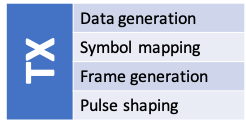

#### Data generation

%no more here in the loop 

#### Symbol mapping

symb_TX_data = mapping_QAM( bit_TX_data , nb_bit_per_symb , nb_bit ) ;      % Map the input bits to complex symbols

#### Frame generation

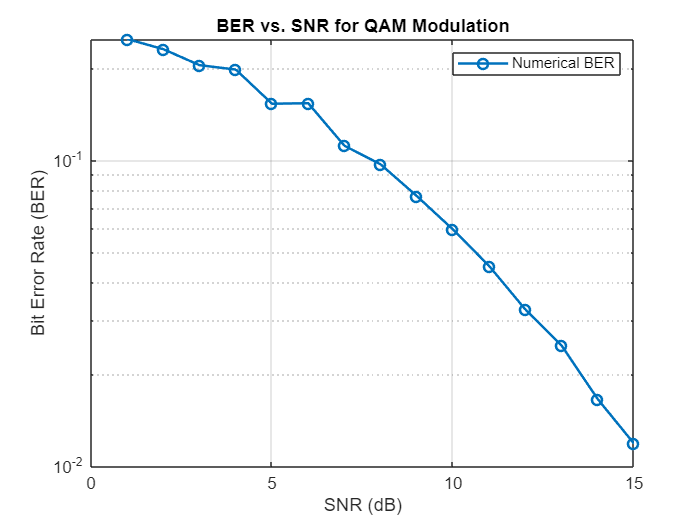

symb_TX = [ symb_pilot ; symb_TX_data ] ;                                   % Concatenate the pilot symbols to the data symbols to transmit

% % TX symbols: constellation plot (symbol space)
% figure
% title( 'TX constellation' )
% hold on
% grid on

% plot( real( symb_TX ) , imag( symb_TX ) , 'or' )
% xlabel('I')
% ylabel('Q')

#### Pulse shaping (TX Filtering)

signal_TX = convolution_TX( symb_TX , g , sps ) ;                           % Generation of the waveform: convolution between the RRC pulse and the symbol stream
t = 0 : 1 / fs : 1 / fs * ( size( signal_TX , 1 ) - 1 ) ;                   % Generation of the time vector for visualization
% 
% figure
% title( 'TX waveform: spectrum' )
% hold on
% grid on
% f = linspace( -fs / 2 ,  fs / 2 , length( t ) ) ;                           % Generation of the frequency vector
% plot( f * 1e-6 , 10 * log10( abs( fftshift( fft( signal_TX ) ) ) ) )
% xlabel('Frequency [MHz]')
% ylabel('|X_{L}(f)| [dB]')

### Propagation Channel

signal_RX_noise_less = H( ind_frame ) * signal_TX ;                         % Received signal after channel but before receiver's hardware (so noise less)

### Receiver (RX): demodulation

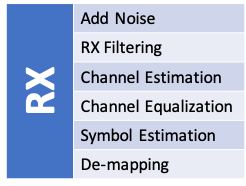

#### Add Noise

% Determination of received signal power
rx_mean_power = sum( abs( signal_TX ).^2 , 1 ) / length( signal_TX ) * sps  ;       % Calculation of the received mean power: use the TX power to get the SNR without fading effect (i.e., assumes average channel power = 1)

% Creating the RX thermal noise (Complex Additive White Gaussian Noise)
noise = ( randn( length( signal_RX_noise_less ) , 1 ) ...
    + 1i * randn( length( signal_RX_noise_less ) , 1 ) ) / sqrt( 2 ) ;              % AWGN with unitary mean power

% Add noise to RX signal
snr = 10^( snr_dB(count) / 10 ) ;
signal_RX = signal_RX_noise_less + noise * sqrt( rx_mean_power / snr ) ;            % Received signal + thermal noise of receiver's hardware

#### RX Filtering

% Convolution between received signal and RRC impulse response and sampling at symbol rate
symb_RX = convolution_RX( signal_RX , g , sps ) ;                                   % Filtering of the RX baseband waveform and sampling every pT
% Removing the delay introduced by the TX and RX filter
symb_RX = symb_RX( span + 1 : end - span ) ;

#### Channel Estimation

H_estimated = symb_RX( 1 : nb_pilot ) ./ symb_TX( 1 : nb_pilot ) ;                  % Least Square CSI estimation: compare TX and RX pilots to estimate the channel 
h_estimated_av = sum( H_estimated , 1 ) / nb_pilot ; % Average the channel estimate over the nb_pilot symbols to obtain a more robust estimate of the channel (noise average)

#### Channel Equalization

symb_RX_data = symb_RX( nb_pilot + 1 : end ) ;                                      % Keep only data symbols (crop the pilots)
symb_RX_data_EQ = symb_RX_data / h_estimated_av ;                                   % Equalization of received data symbols

#### Symbol Estimation

symb_RX_data_estimated = symbol_estimation_QAM( symb_RX_data_EQ , nb_bit_per_symb , nb_data ) ; % By observing RX symbol, make a decision on which TX symbol has been sent

% Received constellation plot (symbol space)
% figure
% title( 'RX constellation' )
% hold on
% grid on
% plot( real( symb_TX_data ) , imag( symb_TX_data ) , '+r' , 'MarkerSize' , 20 , 'LineWidth' , 4 )
% plot( real( symb_RX_data ) , imag( symb_RX_data ) , 'o')
% plot( real( symb_RX_data_EQ ) , imag( symb_RX_data_EQ ) , 'og')
% legend('TX symbols' , 'RX symbols' , 'RX symbols EQ')
% xlabel('I')
% ylabel('Q')

#### Demapping

bit_RX_data = demapping_QAM( symb_RX_data_estimated , nb_bit_per_symb , nb_data ) ;               % Complex-symbols-to-bits demapping

## Bit Error Rate (BER) calculation

[ nb_error , ber_numerical( ind_frame ) ] = biterr( bit_TX_data , bit_RX_data ) ;
end
ber_numerical_averaged = sum( ber_numerical , 2 ) / nb_frame ;
dinara(count) = ber_numerical_averaged;

### Analytical BER calculation

BER analytical expressions exist for some well-known constellations. They can be used to validate your code. Several of those analytical expressions are already implemented in Matlab within the function *berawgn*.

M = 2^nb_bit_per_symb ;                                         % Number of symbols in the constellation
EbNo = snr_dB(count) - 10 * log10 ( nb_bit_per_symb ) ;                % Ratio of bit energy to noise power spectral density, in dB

% BER analytical expression for QAM modulation in AWGN channel
ber_analytical_no_fading = berawgn( EbNo , 'qam' , M );          

% BER analytical expression for QAM modulation in Rayleigh channel
ber_fading_rayleigh = berfading( EbNo , 'qam' , M , 1 );       

% BER analytical expression for QAM modulation in Rice channel
ber_fading_rice = berfading( EbNo , 'qam' , M , 1 , K );         
end
figure;
semilogy(snr_dB, dinara, '-o', 'LineWidth', 1.5, 'DisplayName', 'Numerical BER'); % Plot Numerical BER
grid on; % Enable grid
xlabel('SNR (dB)'); % Label for x-axis
ylabel('Bit Error Rate (BER)'); % Label for y-axis
title('BER vs. SNR for QAM Modulation'); % Title for the plot
legend('show'); % Display legend
